%Load training & test image sets

%Names of characters; images are named "character name"+"number"
%Ex: "amuro1"
names = ["amuro", "ange", "chiyuki",... 
    "gabriel", "kaguya", "katsuhira",... 
    "minene", "nagisa", "nao",... 
    "noriko", "ranpo", "sora",... 
    "tenshi", "vivy", "Chizuru",... 
    "Makise", "Haruhi", "Akutagawa",...
    "Anya", "Denji", "Hitagi", "Hori",...
    "Itadori", "Kazehara", "Mashiro",...
    "Nazuna", "Sakura", "Tohsaka",...
    "Futaba", "Hachiman", "Hayasaka",...
    "Ishigami", "Kaede", "Koga",...
    "Mai", "Nodoka", "Sakuta", "Shirogane",...
    "Shoko", "Yui", "Yukino", "Yuuma"];
[test_chars,test_names,train_chars,train_names] = loadImg(names);

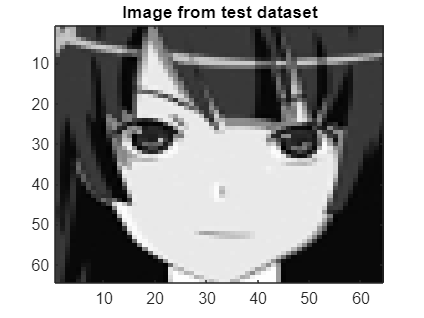

%Testing the model

%Calculate covariance matrix
cov_mat = cov(train_chars);

%Calculate eigenvectors of cov matrix
[V, D] = eigs(cov_mat, 32);

%train data projection
train_projs = train_chars * V;

%Project one image from test dataset

char_idx = 21; %change this to see other character's results

test_char = test_chars(char_idx, :);
test_proj = test_char * V;

%find test point with shortest distance from a train point
iter = length(train_names);
min_idx = getClosest(test_proj,train_projs,iter);

%Display results
figure()
colormap gray
imagesc(reshape(test_char, [64 64]))
title("Image from test dataset")

test_names(char_idx)

ans = "Hitagi3"

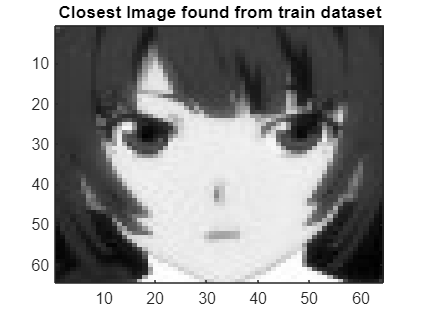

imagesc(reshape(train_chars(min_idx, :), [64 64]))
title("Closest Image found from train dataset")

train_names(min_idx)

ans = "Hitagi2"

% Model accuracy test
iter = length(train_names);
answer = train_names; % List of names
guess = string([]); % List of names

% Run the model for every image in test dataset
for i = 1:iter
    curr_char = (test_chars(i, :))*V;
    guess_idx = getClosest(curr_char,train_projs,iter);
    guess(i) = train_names(guess_idx);
end


num_correct = 0;
for j = 1:iter
    % Remove number from image name ("amuro1" -> "amuro")
    guessed_name = char(guess(j));
    guessed_name = guessed_name(1:end-1);
    correct_name = char(answer(j));
    correct_name = correct_name(1:end-1);

    % If same character, it is correct
    if string(guessed_name) == string(correct_name)
        num_correct = num_correct+1;
    end
end

acc = (num_correct/iter)

acc = 0.7262

% Parameter sweep # of eigenvectors used, and its affects on accuracy

eigenvecs = 1:100; %1-100 eigenvectors
accs = zeros(1, length(eigenvecs));
answer = train_names; % List of names
for  i = eigenvecs
    %Find i number of eigenvectors of cov matrix
    [V_temp, D_temp] = eigs(cov_mat, i);
    
    %projection
    train_projs_i = train_chars * V_temp;
    
    %accuracy
    guess = string([]); % List of names
    
    % Run the model for every image in test dataset
    for j = 1:iter
        curr_char = (test_chars(j, :))*V_temp;
        guess_idx = getClosest(curr_char,train_projs_i,iter);
        guess(j) = train_names(guess_idx);
    end
    
    
    num_correct = 0;
    for k = 1:iter
        % Remove number from image name ("amuro1" -> "amuro")
        guessed_name = char(guess(k));
        guessed_name = guessed_name(1:end-1);
        correct_name = char(answer(k));
        correct_name = correct_name(1:end-1);
    
        % If same character, it is correct
        if string(guessed_name) == string(correct_name)
            num_correct = num_correct+1;
        end
    end
    accs(i) = num_correct/iter;
end

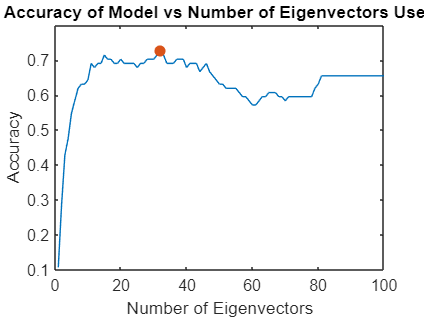

%Plot accuracy vs # of eigenvectors
figure()
plot(accs)
hold on
[max_acc, max_eigs] = max(accs);
plot(max_eigs,max_acc,'.','MarkerSize',20)
xlabel("Number of Eigenvectors");
ylabel("Accuracy");
title("Accuracy of Model vs Number of Eigenvectors Used")

disp("Max accuracy of "+max_acc+" with "+max_eigs+" eigenvectors.")

Max accuracy of 0.72619 with 32 eigenvectors.


% %test against real people
% test_face_names = ["dexter", "mo", "glasses ian", "ollie"]
% test_face_chars = zeros(length(test_face_names), 64*64);
% for i = 1:length(test_face_names)
%     test_face_chars(i,:) = double(reshape(rgb2gray(imread(test_face_names(i) + ".jpg")), [64*64, 1]));
% end
% 
% %test img proj
% char_idx = 4;
% test_char = test_face_chars(char_idx, :);
% test_proj = test_char * V;
% 
% %find test point with shortest distance from a train point
% min_dist = 100000000;
% min_dist_idx = 0;
% for i = 1:length(train_names)
%     temp_char_proj = train_projs(i,:);
%     temp_dist = (test_proj - temp_char_proj).^2;
%     temp_dist = sum(temp_dist);
%     temp_dist = sqrt(temp_dist);
%     if temp_dist < min_dist
%         min_dist = temp_dist;
%         min_dist_idx = i;
%     end
% end
% figure()
% colormap gray
% imagesc(reshape(test_char, [64 64]))
% test_face_names(char_idx)
% imagesc(reshape(train_chars(min_dist_idx, :), [64 64]))
% train_names(min_dist_idx)
